# Test Case - Power Split Drive Unit

mdl = "PowerSplitDriveUnit_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
PowerSplitDriveUnit_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Road grade", dataPoints="[0 1 0; 2 3 0]");
simIn = setBlockParameter(simIn, mdl+"/Road grade", deltaT="0.1");

simIn = setBlockParameter(simIn, mdl+"/Brake force", dataPoints="[0 1 0; 2 3 0]");
simIn = setBlockParameter(simIn, mdl+"/Brake force", deltaT="0.1");

simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", dataPoints="[0 1 0; 2 3 0]");
simIn = setBlockParameter(simIn, mdl+"/MG2 torque command", deltaT="0.1");

simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", dataPoints="[0 1 0; 2 3 0]");
simIn = setBlockParameter(simIn, mdl+"/MG1 torque command", deltaT="0.1");

simIn = setBlockParameter(simIn, mdl+"/Engine torque command", dataPoints="[0 1 0; 2 3 0]");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", deltaT="0.1");

% Initial conditions

simIn = setVariable(simIn, "initial.vehicle_speed_kph", 0);

simIn = setVariable(simIn, "initial.engine_speed_rpm", 0);

simIn = setVariable(simIn, "initial.MG1_Temperature_K", 273.15 + 20);
simIn = setVariable(simIn, "initial.MG1_AirTemp_K", 273.15 + 20);

simIn = setVariable(simIn, "initial.MG2_Temperature_K", 273.15 + 20);
simIn = setVariable(simIn, "initial.MG2_AirTemp_K", 273.15 + 20);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "1000");

% Run simulation
simOut = sim(simIn);

## Visualize Simulation Result

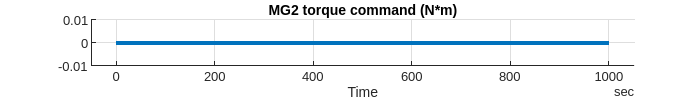

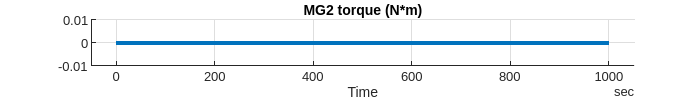

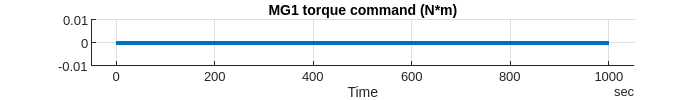

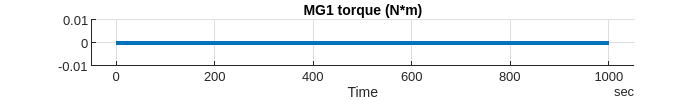

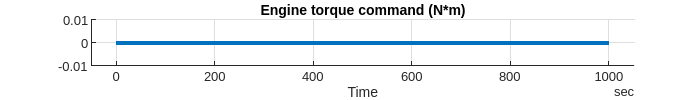

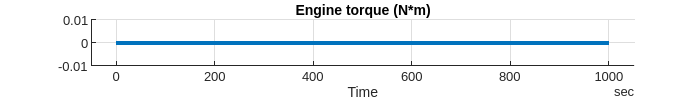

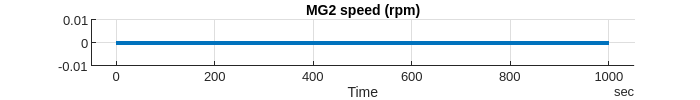

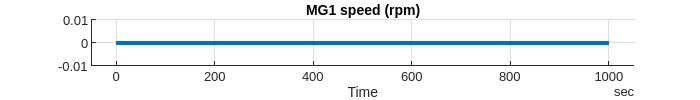

simData = extractTimetable(simOut.logsout);

PowerSplitDriveUnit_Component_plotResults(SimData = simData, FigureHeight = 100);

*Copyright 2021-2022 The Mathworks, Inc.*